# Capítulo 5. Energía y potencia de señales

### Resultado de aprendizaje

Al finalizar este capítulo, el estudiante será capaz de calcular e interpretar la energía y la potencia promedio de señales continuas y discretas, diferenciando señales de energía y señales de potencia mediante expresiones matemáticas, aproximaciones numéricas y simulaciones en MATLAB Live Script.

### 5.1 Introducción

En el análisis de señales y sistemas, dos conceptos fundamentales son la energía y la potencia. Estas magnitudes permiten cuantificar la intensidad, duración y comportamiento global de una señal.

Aunque los términos energía y potencia también se utilizan en física y en circuitos eléctricos, en señales y sistemas se interpretan de forma matemática a partir del valor cuadrático de la señal.

En este capítulo se estudiarán:

- Energía de señales continuas.

- Energía de señales discretas.

- Potencia promedio de señales continuas.

- Potencia promedio de señales discretas.

- Clasificación de señales de energía y señales de potencia.

- Aplicaciones en telecomunicaciones, sensores y procesamiento de señales.

## 5.2 Energía de una señal continua

Para una señal continua x(t), la energía total se define como:

E = integral desde -infinito hasta infinito de `x(t)`^2 dt

Si la energía es finita, la señal puede clasificarse como una señal de energía.

En MATLAB, cuando la señal se representa mediante un vector de muestras, la integral puede aproximarse mediante una suma numérica:

E aproximada = suma `x(t)`^2 * dt

donde dt es el paso de tiempo utilizado para representar la señal.

## Ejemplo 1: Energía de una señal exponencial decreciente continua

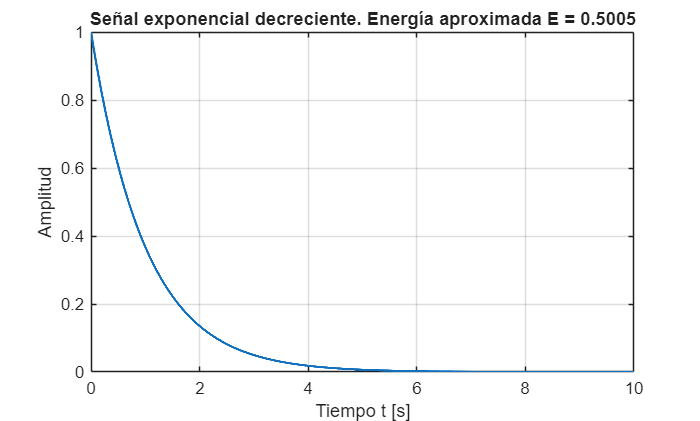

clc;
clear;
close all;

% Vector de tiempo
t = 0:0.001:10;
dt = t(2) - t(1);

% Señal exponencial decreciente
x = exp(-t);

% Cálculo aproximado de energía
E = sum(abs(x).^2)*dt;

% Gráfica
figure;
plot(t, x, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo t [s]');
ylabel('Amplitud');
title(['Señal exponencial decreciente. Energía aproximada E = ', num2str(E)]);


disp(['Energía aproximada de la señal continua: ', num2str(E)]);

Energía aproximada de la señal continua: 0.5005


## Interpretación del Ejemplo 1

La señal exponencial decreciente presenta una amplitud que tiende a cero conforme aumenta el tiempo. Por ello, el área bajo `x(t)`^2 es finita. Este comportamiento permite clasificarla como una señal de energía.

## 5.3 Energía de una señal discreta

Para una señal discreta x[n], la energía total se define como la suma de los valores cuadráticos de la señal:

E = suma desde n = -infinito hasta infinito de `x[n]`^2

En MATLAB, una señal discreta finita se representa mediante un vector, por lo que la energía puede calcularse directamente mediante una sumatoria.

## Ejemplo 2: Energía de una señal discreta finita

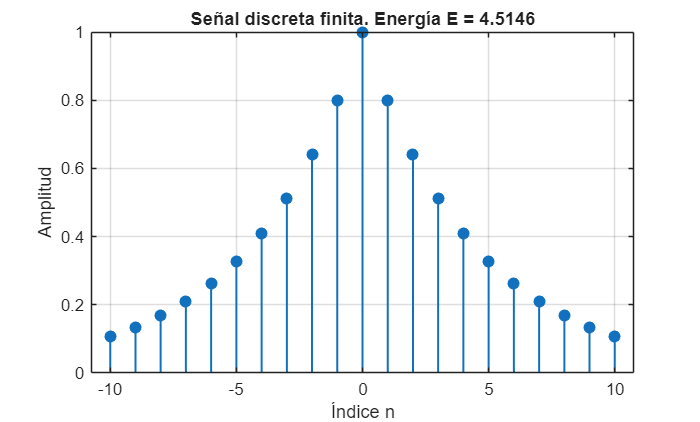

clc;
clear;
close all;

% Índice discreto
n = -10:10;

% Señal discreta finita
x = (0.8).^abs(n);

% Cálculo de energía
E = sum(abs(x).^2);

% Gráfica
figure;
stem(n, x, 'filled', 'LineWidth', 1.2);
grid on;
xlabel('Índice n');
ylabel('Amplitud');
title(['Señal discreta finita. Energía E = ', num2str(E)]);


disp(['Energía de la señal discreta: ', num2str(E)]);

Energía de la señal discreta: 4.5146


## Interpretación del Ejemplo 2

La señal discreta tiene valores significativos alrededor de n = 0 y disminuye conforme el índice se aleja del origen. Su energía es finita porque se está evaluando en un intervalo finito y la amplitud decrece.

## 5.4 Potencia promedio de una señal continua

La potencia promedio de una señal continua se define como:

P = límite cuando T tiende a infinito de (1/(2T)) integral desde -T hasta T de `x(t)`^2 dt

Si la potencia promedio es finita y diferente de cero, la señal puede clasificarse como una señal de potencia.

Las señales periódicas sostenidas, como las sinusoidales ideales, suelen ser señales de potencia.

## Ejemplo 3: Potencia promedio de una señal sinusoidal continua

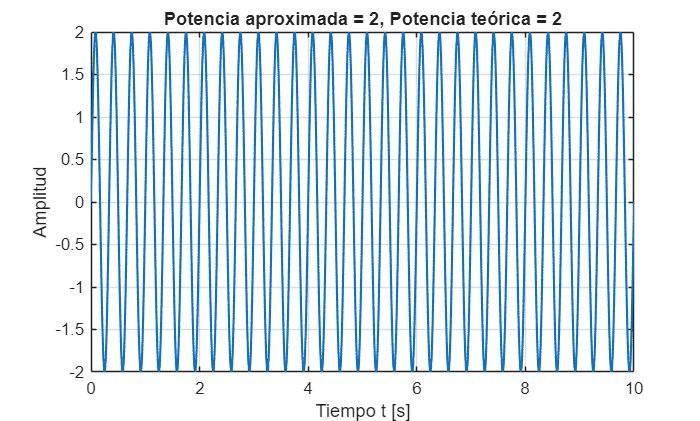

clc;
clear;
close all;

% Vector de tiempo
t = 0:0.001:10;
dt = t(2) - t(1);

% Señal sinusoidal
A = 2;
f = 3;
x = A*sin(2*pi*f*t);

% Potencia promedio aproximada
P = (1/(t(end)-t(1))) * sum(abs(x).^2)*dt;

% Valor teórico para una sinusoidal: A^2/2
P_teorica = A^2/2;

% Gráfica
figure;
plot(t, x, 'LineWidth', 1.3);
grid on;
xlabel('Tiempo t [s]');
ylabel('Amplitud');
title(['Potencia aproximada = ', num2str(P), ', Potencia teórica = ', num2str(P_teorica)]);


disp(['Potencia promedio aproximada: ', num2str(P)]);

Potencia promedio aproximada: 2


disp(['Potencia promedio teórica: ', num2str(P_teorica)]);

Potencia promedio teórica: 2


## Interpretación del Ejemplo 3

La señal sinusoidal no se extingue con el tiempo, por lo que su energía total sería infinita si se considera una duración ilimitada. Sin embargo, su potencia promedio es finita.

## 5.5 Potencia promedio de una señal discreta

Para una señal discreta x[n], la potencia promedio se define como:

P = límite cuando N tiende a infinito de (1/(2N+1)) suma desde n=-N hasta N de `x[n]`^2

En MATLAB, si se trabaja con una cantidad finita de muestras, se puede aproximar la potencia promedio usando el promedio de los valores cuadráticos de la señal.

## Ejemplo 4: Potencia promedio de una señal sinusoidal discreta

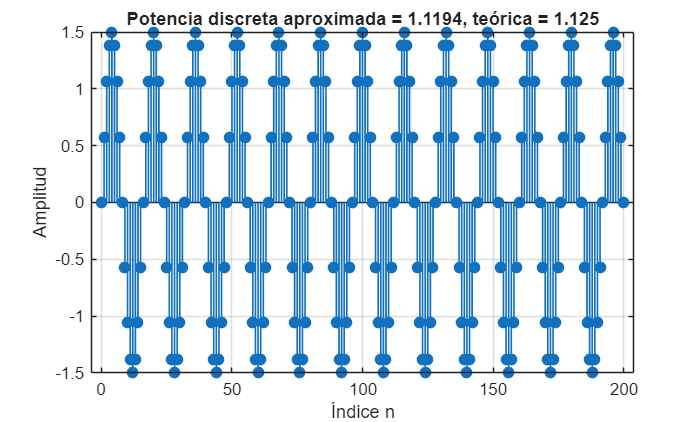

clc;
clear;
close all;

% Índice discreto
n = 0:200;

% Señal sinusoidal discreta
A = 1.5;
omega = pi/8;
x = A*sin(omega*n);

% Potencia promedio aproximada
P = mean(abs(x).^2);

% Valor teórico aproximado para sinusoidal: A^2/2
P_teorica = A^2/2;

% Gráfica
figure;
stem(n, x, 'filled', 'LineWidth', 1.0);
grid on;
xlabel('Índice n');
ylabel('Amplitud');
title(['Potencia discreta aproximada = ', num2str(P), ', teórica = ', num2str(P_teorica)]);


disp(['Potencia promedio discreta aproximada: ', num2str(P)]);

Potencia promedio discreta aproximada: 1.1194


disp(['Potencia promedio teórica: ', num2str(P_teorica)]);

Potencia promedio teórica: 1.125


## Interpretación del Ejemplo 4

La señal sinusoidal discreta mantiene oscilaciones a lo largo del índice n. Por ello, no se considera una señal de energía, sino una señal de potencia.

## 5.6 Señales de energía

Una señal de energía cumple:

0 < E < infinito

y su potencia promedio es:

P = 0

Normalmente, las señales de energía corresponden a señales transitorias o señales de duración limitada. Ejemplos: pulsos finitos, señales exponenciales decrecientes y respuestas transitorias amortiguadas.

## Ejemplo 5: Energía de un pulso rectangular continuo

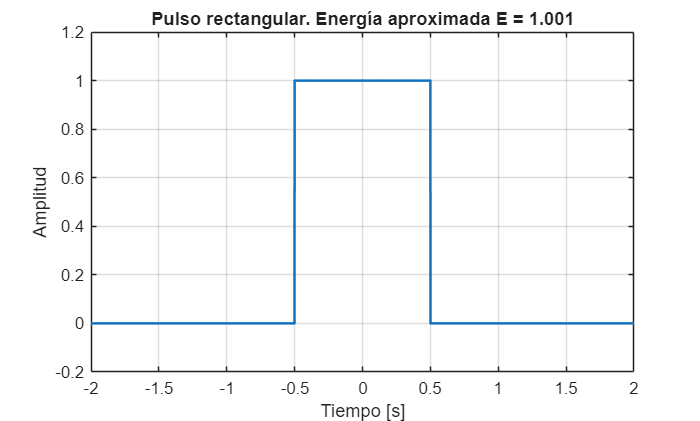

clc;
clear;
close all;

% Vector de tiempo
t = -2:0.001:2;
dt = t(2) - t(1);

% Pulso rectangular entre -0.5 y 0.5
x = double(t >= -0.5 & t <= 0.5);

% Energía aproximada
E = sum(abs(x).^2)*dt;

% Gráfica
figure;
plot(t, x, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Pulso rectangular. Energía aproximada E = ', num2str(E)]);
ylim([-0.2 1.2]);


disp(['Energía aproximada del pulso rectangular: ', num2str(E)]);

Energía aproximada del pulso rectangular: 1.001


## Interpretación del Ejemplo 5

El pulso rectangular tiene duración limitada. Su energía depende de su amplitud y de su ancho temporal. Para un pulso de amplitud 1 y duración 1 segundo, la energía aproximada debe estar cercana a 1.

## 5.7 Señales de potencia

Una señal de potencia cumple:

E = infinito

y:

0 < P < infinito

Normalmente, las señales de potencia corresponden a señales periódicas o señales sostenidas indefinidamente. Ejemplos: señales sinusoidales, señales cuadradas periódicas y portadoras de comunicación ideales.

## Ejemplo 6: Potencia promedio de una señal cuadrada

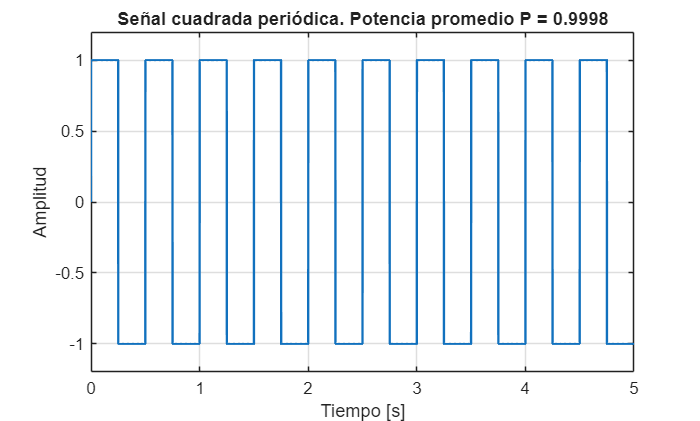

clc;
clear;
close all;

% Tiempo
t = 0:0.001:5;

% Señal cuadrada aproximada sin toolbox
f = 2;
x = sign(sin(2*pi*f*t));

% Cálculo de potencia promedio
P = mean(abs(x).^2);

% Gráfica
figure;
plot(t, x, 'LineWidth', 1.4);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal cuadrada periódica. Potencia promedio P = ', num2str(P)]);
ylim([-1.2 1.2]);


disp(['Potencia promedio aproximada de la señal cuadrada: ', num2str(P)]);

Potencia promedio aproximada de la señal cuadrada: 0.9998


## Interpretación del Ejemplo 6

Una señal cuadrada ideal alterna entre valores positivos y negativos de amplitud constante. Si su amplitud es 1, el valor cuadrático de la señal es aproximadamente 1 en casi todo el intervalo, por lo que su potencia promedio se aproxima a 1.

## 5.8 Comparación entre energía y potencia

Una señal no puede ser simultáneamente señal de energía y señal de potencia en el sentido estricto de la teoría clásica de señales.

Si una señal tiene energía finita, su potencia promedio es cero.

Si una señal tiene potencia finita diferente de cero, su energía total es infinita.

## Ejemplo 7: Comparación entre señal de energía y señal de potencia

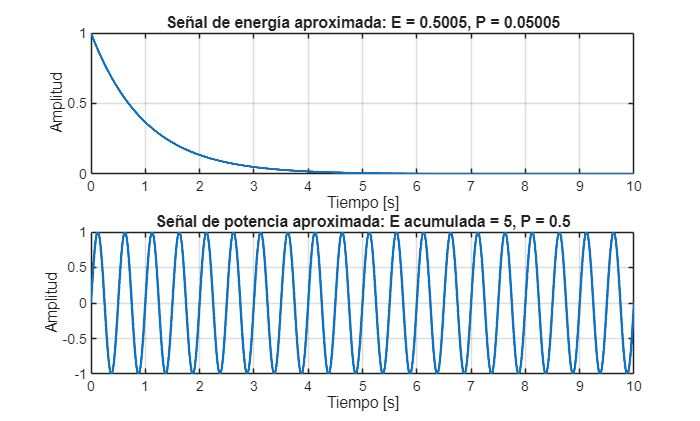

clc;
clear;
close all;

t = 0:0.001:10;
dt = t(2) - t(1);

% Señal de energía
x_energia = exp(-t);

% Señal de potencia
x_potencia = sin(2*pi*2*t);

% Cálculos aproximados
E_x = sum(abs(x_energia).^2)*dt;
P_x = (1/(t(end)-t(1))) * sum(abs(x_energia).^2)*dt;

E_y = sum(abs(x_potencia).^2)*dt;
P_y = (1/(t(end)-t(1))) * sum(abs(x_potencia).^2)*dt;

% Gráficas
figure;

subplot(2,1,1);
plot(t, x_energia, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal de energía aproximada: E = ', num2str(E_x), ', P = ', num2str(P_x)]);

subplot(2,1,2);
plot(t, x_potencia, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal de potencia aproximada: E acumulada = ', num2str(E_y), ', P = ', num2str(P_y)]);

## Interpretación del Ejemplo 7

La señal exponencial decreciente acumula una energía que tiende a un valor finito. La señal sinusoidal, en cambio, acumula cada vez más energía al aumentar el intervalo de observación, pero mantiene una potencia promedio aproximadamente constante.

## 5.9 Energía acumulada de una señal

Una forma útil de analizar una señal es observar cómo se acumula su energía con el tiempo.

E_acumulada(t) = suma acumulada de `x(t)`^2 * dt

Si la energía acumulada tiende a estabilizarse, la señal puede ser de energía. Si crece indefinidamente, la señal puede ser de potencia o no pertenecer a ninguna de las categorías clásicas.

## Ejemplo 8: Energía acumulada

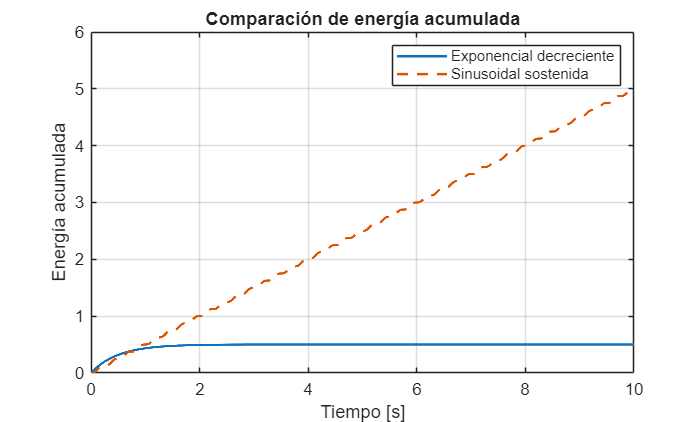

clc;
clear;
close all;

t = 0:0.001:10;
dt = t(2) - t(1);

% Señales
x1 = exp(-t);
x2 = sin(2*pi*2*t);

% Energía acumulada
E_acum_x1 = cumsum(abs(x1).^2)*dt;
E_acum_x2 = cumsum(abs(x2).^2)*dt;

figure;
plot(t, E_acum_x1, 'LineWidth', 1.5);
hold on;
plot(t, E_acum_x2, '--', 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Energía acumulada');
title('Comparación de energía acumulada');
legend('Exponencial decreciente', 'Sinusoidal sostenida');

## Interpretación del Ejemplo 8

La energía acumulada de la exponencial decreciente tiende a estabilizarse. En cambio, la energía acumulada de la señal sinusoidal crece con el tiempo. Esta gráfica permite visualizar la diferencia entre una señal de energía y una señal de potencia.

## 5.10 Potencia de una señal con componente continua

Una señal constante x(t) = A tiene energía infinita si se extiende indefinidamente, pero su potencia promedio es finita:

P = A^2

Esto permite clasificar una señal constante ideal como señal de potencia.

## Ejemplo 9: Potencia de una señal constante

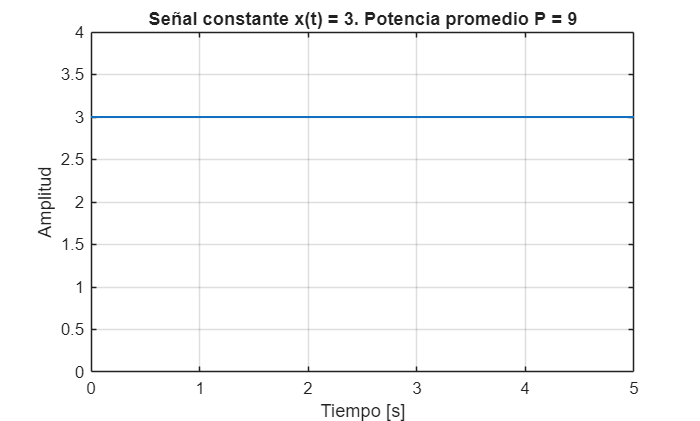

clc;
clear;
close all;

t = 0:0.001:5;

% Señal constante
A = 3;
x = A*ones(size(t));

% Potencia promedio
P = mean(abs(x).^2);

figure;
plot(t, x, 'LineWidth', 1.5);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Señal constante x(t) = 3. Potencia promedio P = ', num2str(P)]);
ylim([0 4]);


disp(['Potencia promedio de la señal constante: ', num2str(P)]);

Potencia promedio de la señal constante: 9


## Interpretación del Ejemplo 9

Una señal constante mantiene su valor para todo tiempo. Por ello, si se considera una duración infinita, su energía total sería infinita. Sin embargo, su potencia promedio es finita e igual al cuadrado de la amplitud.

## 5.11 Energía y potencia en señales con ruido

En aplicaciones reales, muchas señales contienen ruido. La potencia del ruido es una medida importante para evaluar la calidad de una señal, sobre todo en telecomunicaciones y procesamiento digital.

Una medida relacionada es la relación señal a ruido, conocida como SNR. Aquí se calcula una aproximación básica comparando la potencia de la señal útil y la potencia del ruido.

## Ejemplo 10: Potencia de señal útil y ruido

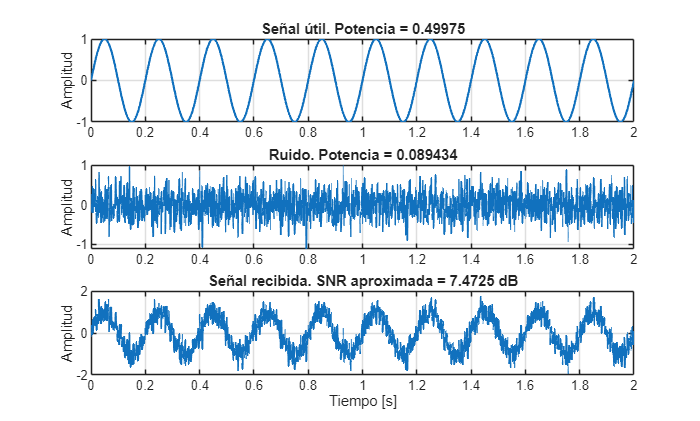

clc;
clear;
close all;

t = 0:0.001:2;

% Señal útil
senal = sin(2*pi*5*t);

% Ruido
ruido = 0.3*randn(size(t));

% Señal contaminada
senal_recibida = senal + ruido;

% Potencias aproximadas
P_senal = mean(abs(senal).^2);
P_ruido = mean(abs(ruido).^2);
P_recibida = mean(abs(senal_recibida).^2);

% SNR aproximada en dB
SNR_dB = 10*log10(P_senal/P_ruido);

figure;

subplot(3,1,1);
plot(t, senal, 'LineWidth', 1.3);
grid on;
title(['Señal útil. Potencia = ', num2str(P_senal)]);
ylabel('Amplitud');

subplot(3,1,2);
plot(t, ruido, 'LineWidth', 1.1);
grid on;
title(['Ruido. Potencia = ', num2str(P_ruido)]);
ylabel('Amplitud');

subplot(3,1,3);
plot(t, senal_recibida, 'LineWidth', 1.2);
grid on;
title(['Señal recibida. SNR aproximada = ', num2str(SNR_dB), ' dB']);
xlabel('Tiempo [s]');
ylabel('Amplitud');


disp(['Potencia de la señal útil: ', num2str(P_senal)]);

Potencia de la señal útil: 0.49975


disp(['Potencia del ruido: ', num2str(P_ruido)]);

Potencia del ruido: 0.089434


disp(['Potencia de la señal recibida: ', num2str(P_recibida)]);

Potencia de la señal recibida: 0.60201


disp(['SNR aproximada en dB: ', num2str(SNR_dB)]);

SNR aproximada en dB: 7.4725


## Interpretación del Ejemplo 10

La potencia de la señal útil y la potencia del ruido permiten estimar la calidad de la señal recibida. Si la potencia del ruido aumenta, la relación señal a ruido disminuye y la señal se vuelve más difícil de interpretar.

## 5.12 Aplicación en telecomunicaciones

En telecomunicaciones, la energía y la potencia de una señal se relacionan con aspectos como intensidad de transmisión, atenuación en el canal, potencia de ruido, calidad de recepción, relación señal a ruido, consumo energético en dispositivos y diseño de filtros y amplificadores.

Una portadora sinusoidal ideal se modela como señal de potencia, mientras que un pulso digital de duración limitada puede modelarse como señal de energía.

## Ejemplo 11: Comparación de dos señales transmitidas con diferente amplitud

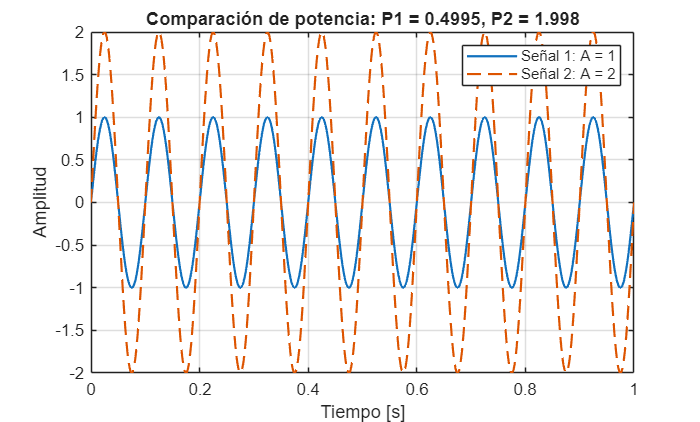

clc;
clear;
close all;

t = 0:0.001:1;

% Señales transmitidas
x1 = sin(2*pi*10*t);
x2 = 2*sin(2*pi*10*t);

% Potencias
P1 = mean(abs(x1).^2);
P2 = mean(abs(x2).^2);

figure;
plot(t, x1, 'LineWidth', 1.3);
hold on;
plot(t, x2, '--', 'LineWidth', 1.3);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title(['Comparación de potencia: P1 = ', num2str(P1), ', P2 = ', num2str(P2)]);
legend('Señal 1: A = 1', 'Señal 2: A = 2');


disp(['Potencia de señal con amplitud 1: ', num2str(P1)]);

Potencia de señal con amplitud 1: 0.4995


disp(['Potencia de señal con amplitud 2: ', num2str(P2)]);

Potencia de señal con amplitud 2: 1.998


## Interpretación del Ejemplo 11

Al duplicar la amplitud de una señal sinusoidal, su potencia no se duplica, sino que aumenta proporcionalmente al cuadrado de la amplitud. Este resultado es importante en telecomunicaciones y electrónica.

## Actividades propuestas

1. Calcule la energía aproximada de x(t) = exp(-2t)u(t) para t entre 0 y 10. 

2. Calcule la energía de x[n] = (0.5)^n para n = 0, 1, ..., 20. 

3. Calcule la potencia promedio de una señal sinusoidal de amplitud 4. 

4. Compare la potencia de dos señales sinusoidales con amplitudes 1 y 3. 

5. Genere un pulso rectangular de amplitud 2 y duración 0.5 segundos. 

6. Genere una señal cuadrada y calcule su potencia promedio. 

7. Simule una señal útil contaminada con ruido y calcule la potencia de ambas. 

8. Analice cómo cambia la SNR cuando aumenta la amplitud del ruido. 

9. Grafique la energía acumulada de una señal exponencial decreciente y de una señal sinusoidal. 

10. Explique si una señal constante ideal debe clasificarse como señal de energía o de potencia.

### Preguntas de reflexión

1. ¿Por qué una señal sinusoidal ideal tiene energía infinita? 

2. ¿Por qué una señal exponencial decreciente puede tener energía finita? 

3. ¿Qué diferencia existe entre energía y potencia promedio? 

4. ¿Por qué la potencia depende del cuadrado de la amplitud? 

5. ¿Qué importancia tiene la potencia del ruido en telecomunicaciones?

### Conclusiones

La energía y la potencia son medidas fundamentales para cuantificar el comportamiento de una señal. La energía se asocia principalmente con señales transitorias o de duración limitada, mientras que la potencia promedio se asocia con señales sostenidas o periódicas.

Las señales de energía tienen energía finita y potencia promedio nula. Las señales de potencia tienen energía infinita y potencia promedio finita. Esta clasificación permite seleccionar herramientas de análisis adecuadas y comprender fenómenos físicos y computacionales.

En MATLAB Live Script, estos conceptos pueden estudiarse mediante aproximaciones numéricas, cálculo de sumas, promedios, integrales discretas y visualización gráfica.

### Bibliografía básica

- Oppenheim, A. V., Willsky, A. S., & Nawab, S. H. Señales y sistemas.

- Lathi, B. P. Linear Systems and Signals.

- Haykin, S., & Van Veen, B. Signals and Systems.

- Proakis, J. G., & Manolakis, D. G. Digital Signal Processing.

- MathWorks Documentation. MATLAB Live Editor.